# ROBUSTNESS

Investigates robustness of MPC-PD controller.

## cubewithpanels0

%models
loop_real = 'cubewithpanels0_mpcpd';
loop_model = 'cube0_mpcpd_model';
sc_real = 'cubewithpanels0';
sc_model = 'cube0_model';

open(loop_real);
set_param(loop_real, 'FastRestart', 'on',  'SaveState', 'on', 'StateSaveName', 'states', 'MaxStep', '1');
open(loop_model);
set_param(loop_model, 'FastRestart', 'on', 'SaveState', 'on', 'StateSaveName', 'states');

%params
t_tot = 400;
tar = 3;
costfunction = 1;

%mpcpd params
pred_horizon = 50;
cont_update = 10;
g = [1; 1; 1; 50; 50; 50];

### cube0

1_cubewithpanels0_cube0_1

%info
filename = '1_cubewithpanels0_cube0_1';
info = '1: 50 10 [1 1 1 50 50 50] 5 0.2 EG (e^2 + 0.01k^2) with cube0 model';

%params
iterations = 25;
learning_rate = 0.1;

%sim
simmpcpd;
prepvisualise;

%clean
close all;
clear;

## realvleospacecraft0

%models
loop_real = 'realvleospacecraft0_mpcpd';
loop_model = 'cube0_mpcpd_model';
sc_real = 'realvleospacecraft0';
sc_model = 'cube0_model';

open(loop_real);
set_param(loop_real, 'FastRestart', 'on',  'SaveState', 'on', 'StateSaveName', 'states', 'MaxStep', '1');
open(loop_model);
set_param(loop_model, 'FastRestart', 'on', 'SaveState', 'on', 'StateSaveName', 'states');

%params
t_tot = 200;
tar = 3;
costfunction = 1;

%disturbances
no_tau_dist = [0 0 0];
no_tau_dist_ser = timeseries(no_tau_dist, 0);

%mpcpd params
pred_horizon = 50;
cont_update = 10;
g = [1; 1; 1; 50; 50; 50];

### cube0

1_realvleospacecraft0_cube0_1

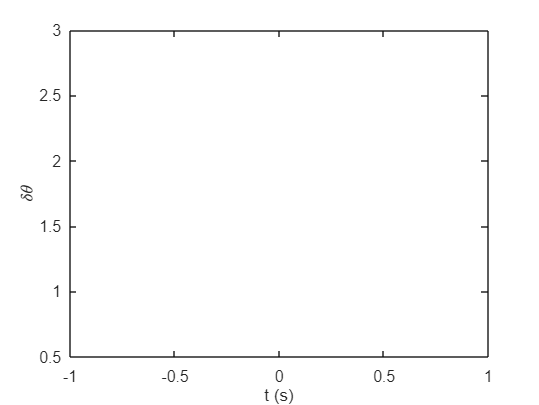

Error using matlab.internal.math.getdimarg
Dimension argument must be a positive integer scalar within indexing
range.

Error in cumtrapz>getDimArg (line 91)
    dim = matlab.internal.math.getdimarg(dim);

Error in cumtrapz (line 49)
    dim = min(ndims(y)+1, getDimArg(

%info
filename = '1_realvleospacecraft0_cube0_1';
info = '1: 50 10 [1 1 1 50 50 50] 25 0.1 EG (e^2 + 0.01k^2) with cube0 model';

%params
iterations = 25;
learning_rate = 0.1;
tau_dist_ser = no_tau_dist_ser;

%sim
simmpcpd;
prepvisualise;


%clean
close all;
clear;